# Laboratorio No. 5 - Robótica de Desarrollo, Cinemática Inversa - Robótica

INTEGRANTES:

Victor Manuel Dávila Castañeda.

Manuel Felipe Carranza Montenegro.

%clc;
clear all;
%addpath('/Users/macuser/MATLAB-Drive/RVC1/rvctools/');
%addpath('/home/macuser/MATLAB-Drive/RVC1/rvctools/');

**Robot PhantomX Pincher.**

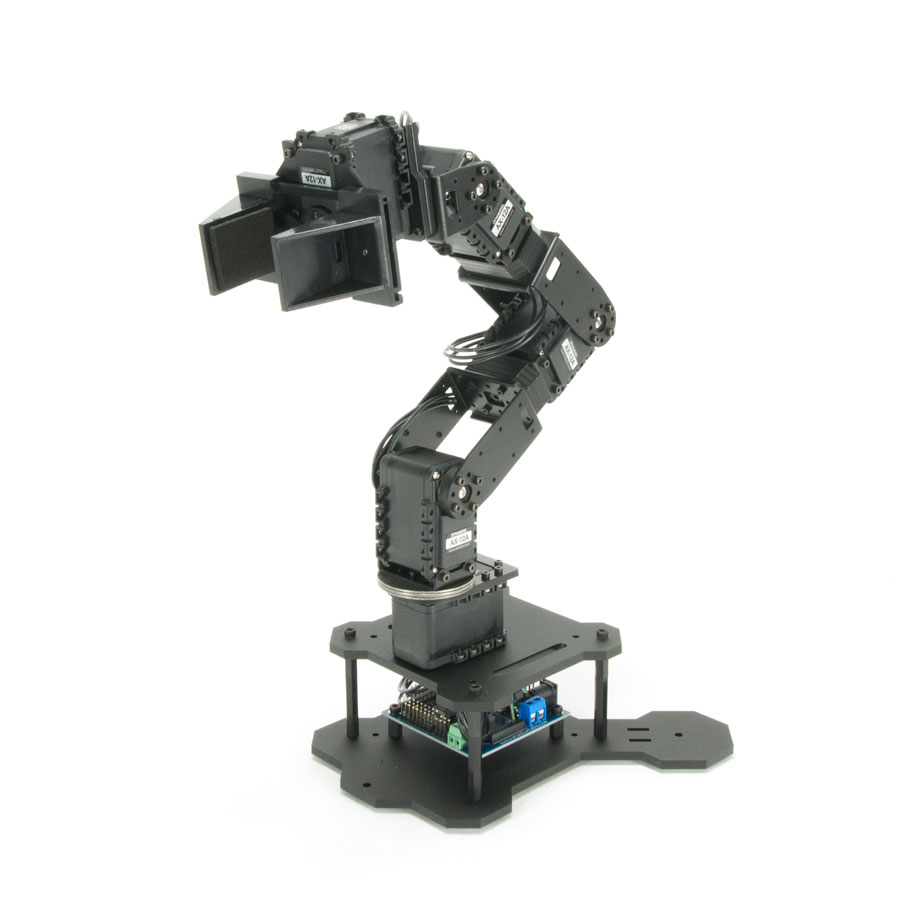

**Eslabones y las Articulaciones.**

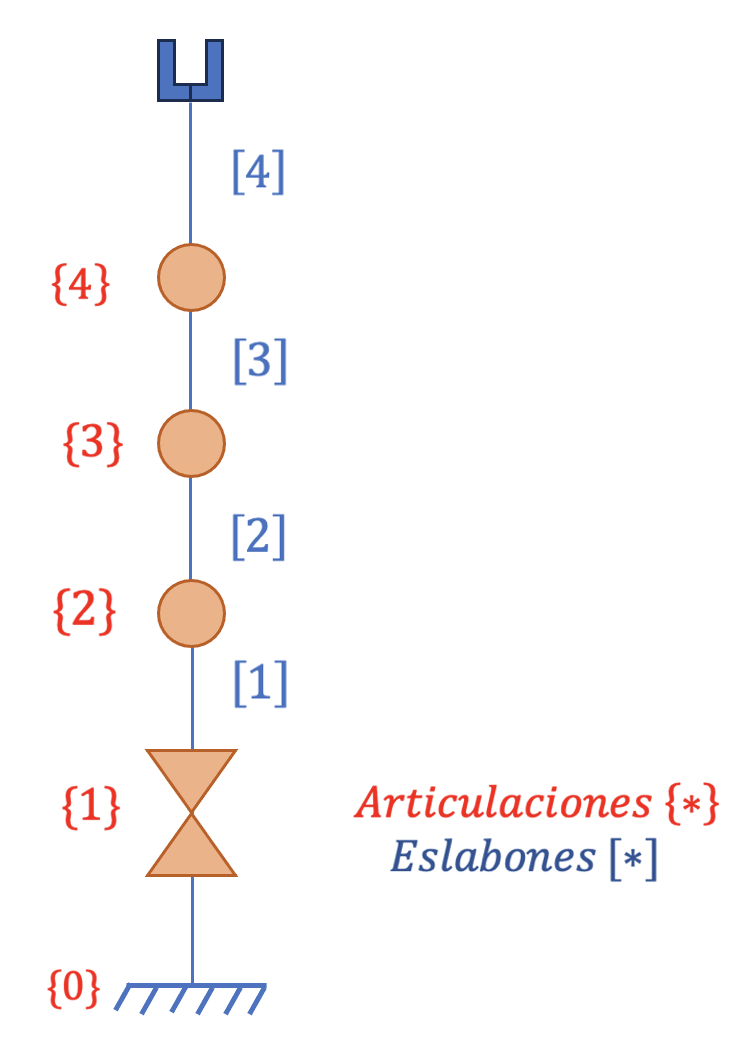

**Sistemas de Referencia según la Convención DHstd.**

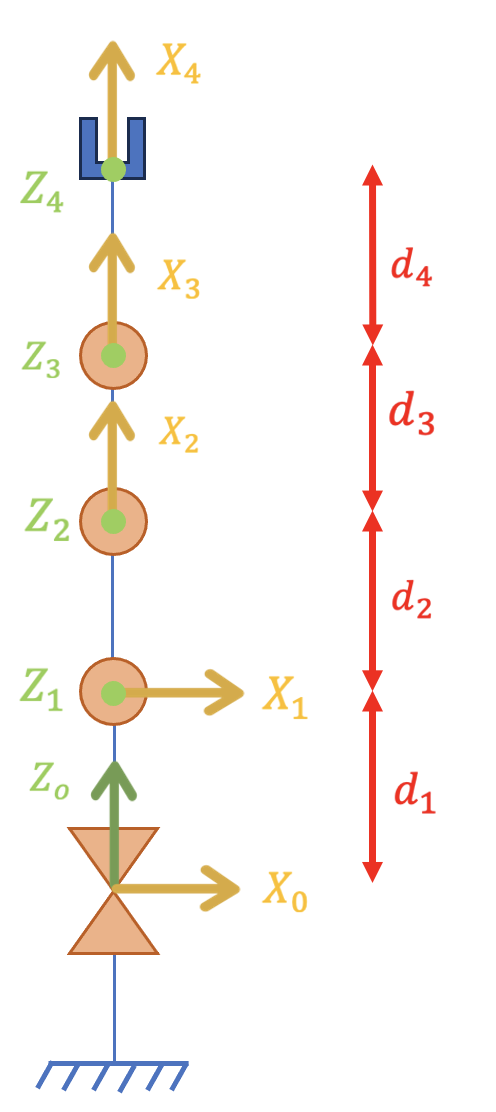

**Parámetros de acuerdo con la Convención DHstd.**


$$\begin{array}{||c|c|c|c|c|}
\hline
Link \space (i) & \theta_{i} & d_{i} & \alpha_{i} & a_{i} & Offset\\ 
\hline
1 &  q_{1} & 152.05 & \frac{\pi}{2} & 0 & 0 \\
\hline
2 & q_{2} & 0 & 0 & 136.82 & \frac{\pi}{2} \\
\hline
3 & q_{3} & 0 & 0 & 74.12 & 0 \\
\hline
4 & q_{4} & 0 & 0 & 108.4 & 0 \\
\hline
\end{array}$$





% Definición de los parámetros del robot
l_1 = 152.05; 
l_2 = 136.82; 
l_3 = 74.12;
l_4 = 108.4;

% Creación de un objeto de enlace para cada Articulación
L(1) = Link('revolute', 'qlim', [0 pi], 'd', l_1, 'a', 0, 'alpha', pi/2);
L(2) = Link('revolute', 'qlim', [0 pi], 'd', 0, 'a', l_2, 'alpha', 0, 'offset', pi/2);
L(3) = Link('revolute', 'qlim', [0 pi], 'd', 0, 'a', l_3, 'alpha', 0);
L(4) = Link('revolute', 'qlim', [0 pi], 'd', 0, 'a', l_4, 'alpha', 0);

% Creación del Objeto de Robot Serial
ROBOT = SerialLink(L, 'name', 'Robot')

 
ROBOT = 
 
Robot (4 axis, RRRR, stdDH, fastRNE)                             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      152.1|          0|      1.571|          0|
|  2|         q2|          0|      136.8|          0|      1.571|
|  3|         q3|          0|      74.12|          0|          0|
|  4|         q4|          0|      108.4|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1            


% Definición de la Herramienta (Tool) del Robot
ROBOT.tool = trotx(0) * transl(0, 0, 0)

 
ROBOT = 
 
Robot (4 axis, RRRR, stdDH, fastRNE)                             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      152.1|          0|      1.571|          0|
|  2|         q2|          0|      136.8|          0|      1.571|
|  3|         q3|          0|      74.12|          0|          0|
|  4|         q4|          0|      108.4|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1            


% Visualización del Robot en la Configuración Inicial
ROBOT.plot([0 0 0 0], 'notiles', 'noname');

% Establecer Límites de Visualización
xlim([-471 471])
ylim([-471 471])
zlim([-288 655])

view([-64 25])

% Matriz de Transformación Homogenea para cada Eslabón
syms q1 q2 q3 q4 q5 q6
H10 = trotz(q1) * transl(0, 0, l_1) * transl(0, 0, 0) * trotx(pi/2);
H21 = trotz(q2) * transl(0, 0, 0) * transl(l_2, 0, 0) * trotx(0);
H32 = trotz(q3) * transl(0, 0, 0) * transl(l_3, 0, 0) * trotx(0);
H43 = trotz(q4) * transl(0, 0, 0) * transl(l_2, 0, 0) * trotx(0);
H60 = H10 * H21 * H32 * H43;
H60 = simplify(H60)

T=[1 0 0 100;
    0 1 0 100;
    0 0 1 200;
    0 0 0 1
    ]

T =      1     0     0   100
     0     1     0   100
     0     0     1   200
     0     0     0     1


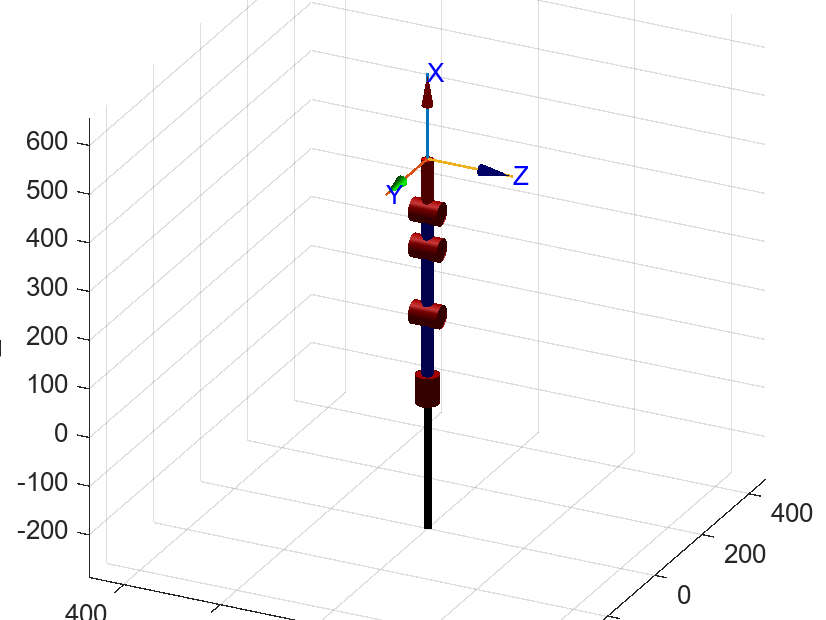


% Cinemeatica Inversa
%q = ROBOT.ikine(T, 'q0', [0 0 0 0], 'mask', [100 100 200 0 0 0])

ROBOT.plot([0 0 0 0], 'notiles', 'noname');


V = [210 50 l_1;
     160 0 l_1;
     210 -50 l_1;
     200 -50 l_1+5;
    ];
M = [150 50 l_1+5;
     150 50 l_1;
     V(1,:);
     V(2,:);
     V(3,:);
     150 -50 l_1
    ];
d1=deg2rad(-120)

d1 = -2.0944

d2=deg2rad(-80)

d2 = -1.3963

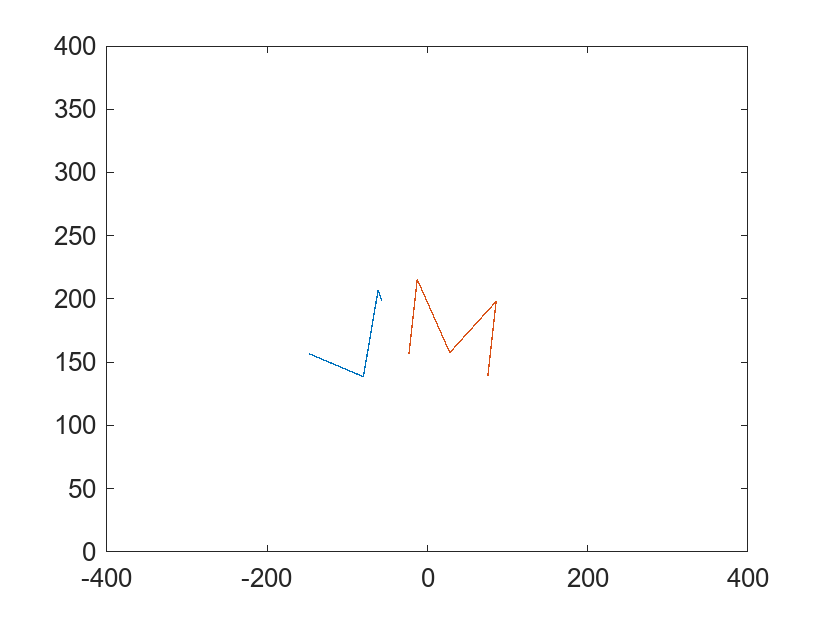

R1 = [cos(d1) -sin(d1) 0;
     sin(d1) cos(d1) 0;
     0 0 1
    ];
R2 = [cos(d2) -sin(d2) 0;
     sin(d2) cos(d2) 0;
     0 0 1
    ];
V = V * R1;
M = M * R2;
T=[1 0 0 100;
    0 1 0 100;
    0 0 1 200;
    0 0 0 1
    ];

plot(V(:,1),V(:,2))
hold on
plot(M(:,1),M(:,2))
xlim([-400 400])
ylim([0 400])


% Cinemeatica Inversa
qs= [0 0 0 0];
for i = 1:length(V(:,1))+length(M(:,1))
    qs(i,:)=[0 0 0 0];
end
%calculamos todas las cinematicas inversas


for i = 1:length(V(:,1))
    x = V(i, 1);
    y = V(i, 2);
    th=atan2(y,x);
    x= x-l_3*cos(th);
    y=y-l_3*sin(th);
    z = V(i, 3);
    L = sqrt(x^2 + y^2);
    c = sqrt(L^2 + z^2);
    c3 = (c^2 - l_2^2 - l_3^2)/(2 * l_2 * l_3);
    s3 = sqrt(1 - c3^2);
    k1 = l_2 + l_3 * c3;
    k2 = l_3 * s3;
    theta = atan2(z, L) - atan2(k2, k2);
    T(1:3,4) = V(i,:)';
    qs(i+1, 1) = pi/2 - atan2(y, x);
    qs(i+1, 2) = pi/2 - theta;
    qs(i+1, 3) = atan2(sqrt(1 - c3^2), c3);
    qs(i+1, 4) = -((pi/4) - qs(i, 2) - qs(i, 3));
end

for i = length(V(:,1))+1:length(V(:,1))+length(M(:,1))
    x = M(i-length(V(:,1)), 1);
    y = M(i-length(V(:,1)), 2);
    th=atan2(y,x);
    x= x-l_3*cos(th);
    y=y-l_3*sin(th);
    z = M(i-length(V(:,1)), 3);
    L = sqrt(x^2 + y^2);
    c = sqrt(L^2 + z^2);
    c3 = (c^2 - l_2^2 - l_3^2)/(2 * l_2 * l_3);
    s3 = sqrt(1 - c3^2);
    k1 = l_2 + l_3 * c3;
    k2 = l_3 * s3;
    theta = atan2(z, L) - atan2(k2, k2);
    qs(i+1, 1) = pi/2 - atan2(y, x);
    qs(i+1, 2) = pi/2 - theta;
    qs(i+1, 3) = atan2(sqrt(1 - c3^2), c3);
    qs(i+1, 4) = -((pi/4) - qs(i, 2) - qs(i, 3));
end

qs =          0         0         0         0
   -0.7573    1.5358    0.3576   -0.7854
   -0.5236    1.2995    1.2559    1.1080
   -0.2899    1.5358    0.3576    1.7701
   -0.2786    1.4845    0.4912    1.1080
   -0.1472    1.2765    1.1917    1.1902
   -0.1472    1.2901    1.2725    1.6828
   -0.0592    1.5358    0.3576    1.7772
    0.1745    1.2995    1.2559    1.1080
    0.4083    1.5358    0.3576    1.7701
